### The Prime Number Theorem

In his work Elements, Euclid first proved that there exist infinitely many prime numbers in c.300 BC. 

For $x>1$, the number of primes less than or equal to $x$ is denoted by $\pi(x)$. Euclid's theorem implies that $\pi(x) \rightarrow \infty$ ($x \rightarrow \infty$).

The Prime Number Theorem provides the behavior of $\pi(x)$ as $x\rightarrow \infty$ and the information of the distribution of primes:


$$\frac{\pi(x)}{\frac{x}{\log{x}}} 
\rightarrow 1
\quad
(x \rightarrow \infty).$$


In 1896, the Prime Number Theorem was proved by Jacques Hadamard and Charles Jean de la Vallée-Poussin independently.

The following graphs visualize 

- The difference $\pi(x) - \frac{x}{\log{x}} \rightarrow \infty$ as $x \rightarrow \infty$.

- The convergence of $\frac{\pi(x)}{\frac{x}{\log{x}}} $ is very slow. 

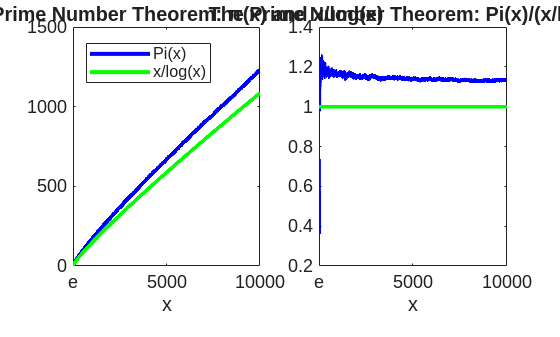

P=zeros(1,10000);
P(1,1)=1;
P(1,2)=1;
L=zeros(1,10000);
L(1,1)=3/log(3);
L(1,2)=3/log(3);
N=zeros(1,10000);
N(1,1)=1;
N(1,2)=2;
M=ones(1,10000);

for i=3:10000
    A=zeros(1,i);
    for j=1:i
        A(1,j)=double(isprime(j));
    end
    P(1,i)=sum(A(1,:));
    L(1,i)=i/log(i);
    N(1,i)=i;
end

newcolors = [0 0 1; 
             0 1 0; 
             1 0 0];
colororder(newcolors)

subplot(1,2,1)
plot(N,P,N,L,'LineWidth',2)
title('The Prime Number Theorem: π(x) and x/log(x)')
xlabel('x');
xticks([1 5000 10000]);
xticklabels({'e','5000','10000'});
legend('Pi(x)','x/log(x)','Location','northwest');

subplot(1,2,2)
plot(N,P./L,N,M,'LineWidth',2)
title('The Prime Number Theorem: Pi(x)/(x/log(x))')
xlabel('x');
xticks([1 5000 10000]);
xticklabels({'e','5000','10000'});


%saveas(gcf,'pnt.png');

### The Green-Tao Theorem

In 2004 Ben Green and Terence Tao proved the following historical theorem in number theory: 

***The prime numbers contain infinitely many arithmetic progressions of length $k$ for all $k$.***

The original paper is [here](https://doi.org/10.4007/annals.2008.167.481).

We explore such arithmetic progressions $\{x_n\}_{n=1}^k$ using Julia.  

Note that 

- If $x_1=2$, then $k\leq2$. 

- If $x_1\ne2$, then the common difference of successive members is even. 

- If the final digit of $x_1$ is $5$, then $k\leq5$.

So we investigate such arithmetic progressions of the form:


$$x_n=(a+10b)+2c\times(n-1), \quad n=1,2,3,\cdots,k,$$


where $x_1=a+10b$ is the first term, $2c$ is the common difference, $a=1,3,7,9$, and $b,c=1,2,3,\cdots$.

k=7

k = 7

a=[1 3 7 9];
P=zeros(1,k);
Q=zeros(1,k);
for i=1:k
    Q(1,i)=i;
end
L=ones(1,k);

for i=1:4
    for b=0:2000
        for c=1:1000
            for l=1:k
                P(1,l)=a(1,i)+10*b+2*c*(l-1);
            end
            if isprime(P)==logical(L)
               disp(P) 
               Q=[Q;P];
            end
        end
    end
end

         881        1091        1301        1511        1721        1931        2141

        1061        1901        2741        3581        4421        5261        6101

        1091        1301        1511        1721        1931        2141        2351

        1811        3701        5591        7481        9371       11261       13151

        1931        3191        4451        5711        6971        8231        9491

        2801        4271        5741        7211        8681       10151       11621

        5651        6491        7331        8171        9011        9851       10691

        8191        9661       11131       12601       14071       15541       17011

        9661       11131       12601       14071       15541       17011       18481

       10861       11701       12541       13381       14221       15061       15901

       11261       12101       12941       13781       14621       15461       16301

       11261       12941       14621       16301      

Q=Q(2:end,:);
                    
%writematrix(Q,'gt.csv')

### The abc Conjecture

This is a conjecture emerged during the discussion of Joseph Oesterlé and David Masser in 1985. To state this we introcude abc triplet and the radical. Denote by $\mathbb{N}$ the set of all positive integers. 

The set of abc triplets is defined by 


$$X:=
\{
(a,b,c)\in\mathbb{N} : a<b<c, a+b=c, 
\text{gcd}(a,b)=\text{gcd}(b,c)=\text{gcd}(c,a)=1
\}.$$


If $a+b=c$ and $\text{gcd}(a,b)=1$, then we have $\text{gcd}(b,c)=\text{gcd}(c,a)=1$ and 


$$X=
\{
(a,b,c)\in\mathbb{N} : a<b<c, a+b=c, 
\text{gcd}(a,b)=1
\}.$$


If the prime factorization of $N
$ is given by 


$$N=p_1^{m(1)} \dots p_k^{m(k)},
\quad
p_1<\dots<p_k,
\quad
m(1),\cdots,m(k)\in\mathbb{N},$$


then the radical of $N$ is defined by 


$$\text{rad}(N):=p_1 \dots p_k.$$


For example


$$\text{rad}(2145825)
=\text{rad}(3^3\cdot5^2\cdot11\cdot17^2)
=3\cdot5\cdot11\cdot17
=2805.$$


For $\kappa\geq1$, set


$$X[\kappa]
:=
\{(a,b,c) \in X : c \geq \bigl(\text{rad}(abc)\bigr)^\kappa
\}.$$


### The abc conjecture: $|X[\kappa]| <\infty $ for any $\kappa>1$.

Shinichi Mochizuki claimed to have a proof in 2012, and the four papers were published in 2020. 

We now remark some properties of $X[\kappa]$:

- If $\kappa<\mu$, then $X[\mu] \subset X[\kappa]$.

- We have $(1,8,9),(5,27,32){\in}X[1]$ since 


$$\text{rad}(1\cdot8\cdot9)
=
\text{rad}(1\cdot2^3\cdot3^2)
=
2\cdot3=6<9,$$



$$\text{rad}(5\cdot27\cdot32)
=
\text{rad}(5\cdot3^3\cdot2^5)
=
5\cdot3\cdot2=30<32.$$


- We have $\{(1,3^{2^k}-1,3^{2^k})\}_{k=1}^\infty \subset X[1]$ and $|X[1]|=\infty$. Indeed we deduce that 


$$b
=
(3^{2^{k-1}}+1)(3^{2^{k-1}}-1)
=
\cdots
=
\prod_{l=1}^{k-1}
(3^{2^l}+1)
\times
(3+1)
(3-1).$$


and $b=3^{2^k}-1$ is a multiple of $2^{k+2}$ since $3+1=4=2^2$. The we have 


$$\text{rad}\bigl(1\cdot(3^{2^k}-1)\cdot3^{2^k}\bigr)
=
\text{rad}\left(1\cdot\frac{3^{2^k}-1}{2^{k+1}}\cdot3\right)
\leq
\frac{3(3^{2^k}-1)}{2^{k+1}}
\leq
\frac{3(3^{2^k}-1)}{4}
<
3^{2^k}
=c.$$


- The confirmed elements of $X[1.6]$ are 


$$(2, 3^{10}\cdot109, 23^5),
\quad
(11^2, 3^2\cdot5^6\cdot7^3, 2^{21}\cdot23), 
\quad
(19\cdot1307, 7\cdot29^2\cdot31^8, 2^8\cdot3^{22}\cdot5^4).$$


- There is no confirmed element of $X[2]$. 

kappa= 1.25

kappa = 1.2500

Z=[];
for a=1:500
    for b=a+1:a+2500
        c=a+b;
        X=factor(a*b*c);
        L=length(X);
        rad=X(1,1);
        if gcd(a,b)==1
            for i=2:L
                if X(1,i)==X(1,i-1)
                    rad=rad*1;
                else
                    rad=rad*X(1,i);
                end
            end
            if (c >= rad^kappa)
                z=[a b c];
                Z=[Z;z];
            end
        end
    end
end

[Y,I]=sort(Z(:,3));
Z=Z(I,:);
[Y,I]=sort(Z);
Y

Y =            1          80          81
           1         125         128
           1         242         243
           1         243         256
           3         512         513
           5        1024        1029
          10        2187        2197
          13        2400        2401


Invalid use of operator.